# TEMPERATURE AND SPEED CONTROL LAB (TSC-LAB)

#### Practice 10: Data acquisition with square velocity input

[https://tsc-lab.blogspot.com/2021/06/practice-10-data-acquisition-with.html](https://tsc-lab.blogspot.com/2021/06/practice-10-data-acquisition-with.html)

- Blog: [https://tsc-lab.blogspot.com/](https://tsc-lab.blogspot.com/)

- GitHub: [https://github.com/vasanza/TSC-Lab](https://github.com/vasanza/TSC-Lab)

- Matlab functions: [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `IEEEDataPort: `[http://ieee-dataport.org/4138](http://ieee-dataport.org/4138)

- `TSC-LAB configurations`

- `int dutyCycleInitial = 255;`

- `int dutyCycleFinish = 0;`

- `int period = 13000;`

- `int cycles = 50;`

- `1 sample per second`

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder

# Raw dataset preprocessing

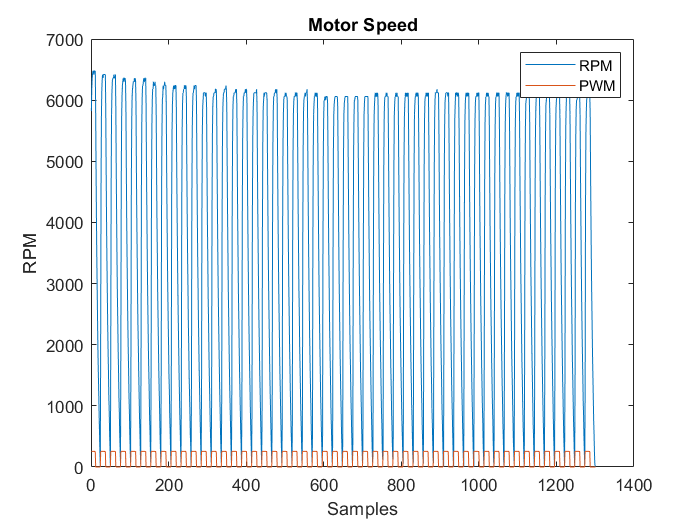

filenames = FindCSV(datapath);%List All CSV files
data=readtable(fullfile(datapath,filenames(1).name));%Select i CSV file
data=table2array(data);

DataNorm = fNormalization(data(:,1));%Normalization
DataFeatures = [max(DataNorm) min(DataNorm) mean(DataNorm)...
    median(DataNorm) rms(DataNorm) std(DataNorm) ];%Feature extraction

# Plot Raw TSC-LAB dataset

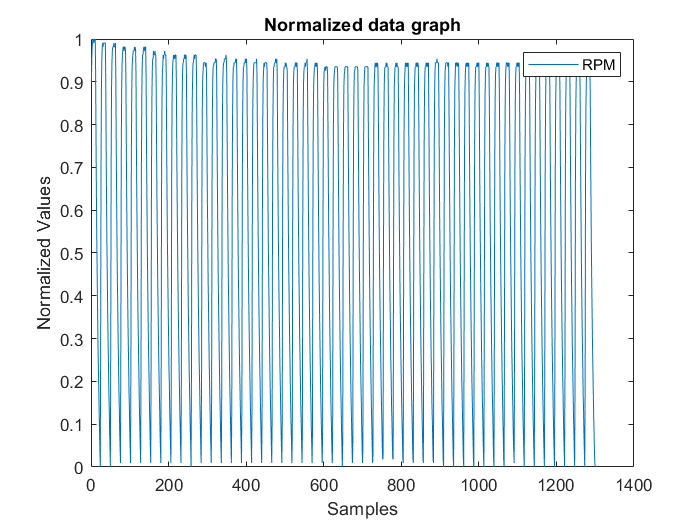

figure

plot(data);xlabel('Samples');ylabel('RPM');
title('Motor Speed');
legend('RPM','PWM');

# Plot Normalization dataset

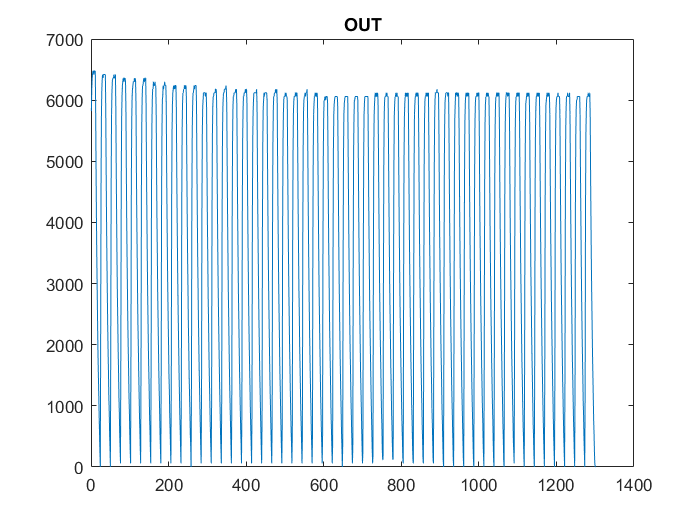

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized data graph');

legend('RPM');

# Select a case

                                                                    
Created preference file C:\Users\vasan\Documents\MATLAB\idprefs.mat.
Type HELP MIDPREFS if you want to move this file.                   


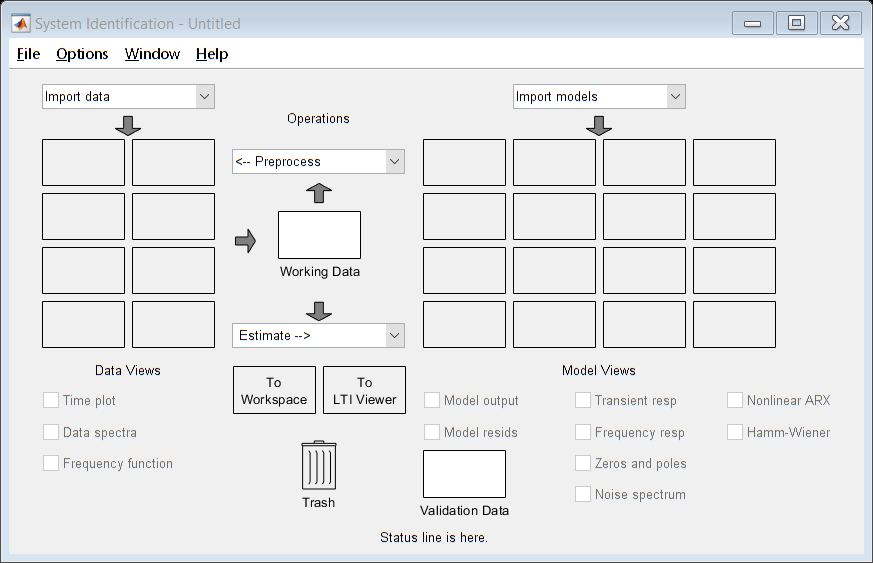

IN=data(:,end);%temp1

OUT=data(:,1);%PWM1
figure
plot(OUT)
title('OUT');

# System Identification

ident

# Open the Classification Learner

%regressionLearner
%classificationLearner